# Hands-On: Estimation of the Static Response Curve of Level Sensors

## Introduction

### What is the static response of a sensor?

The static response of a sensor can be determined by assuming that the sensor input is constant and by ignoring the sensor dynamics. The resulting static response map characterizes the output of the sensor after all transients have settled and the output has converged to a steady-state response.

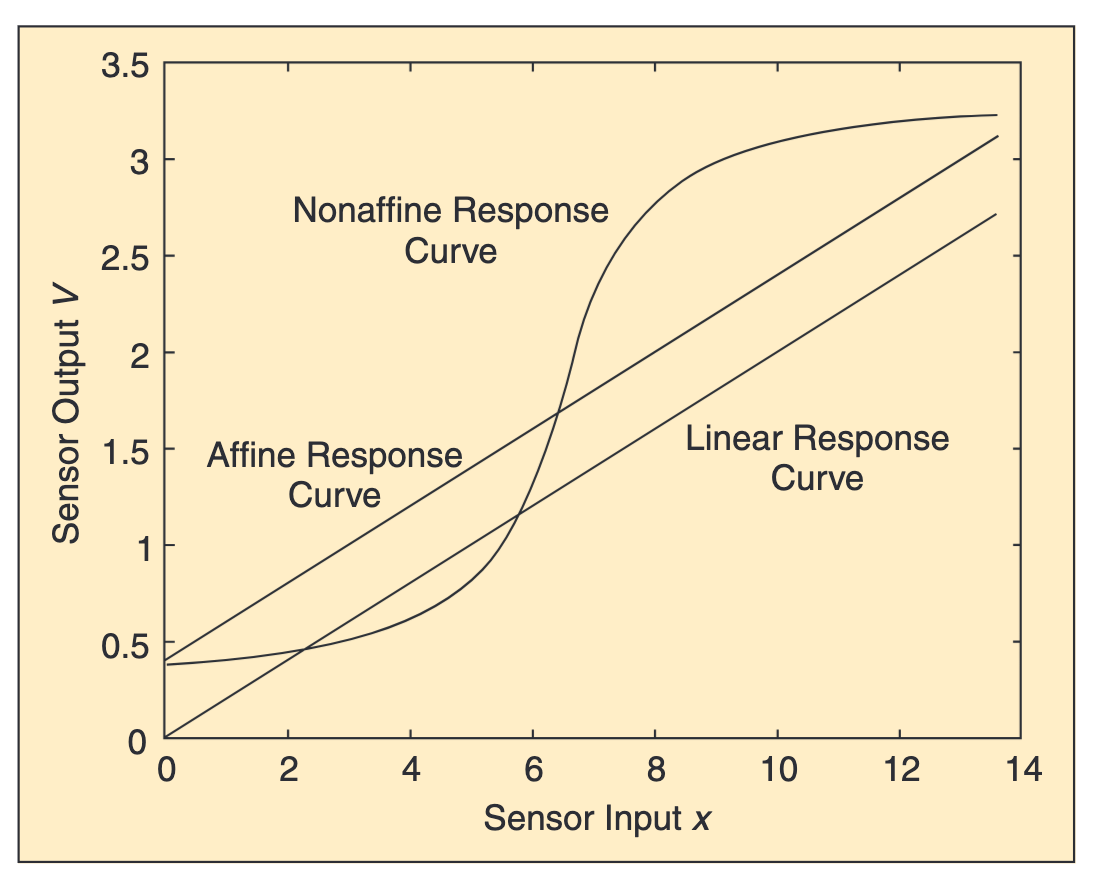

Examples fo static sensor response curves (excerp from [1]).

clear
close all
clc

## An Experiment: Static Response Curve of a Piezoresistive Pressure Sensor

We want to calibrate the level sensors of a Three-Tank-System 

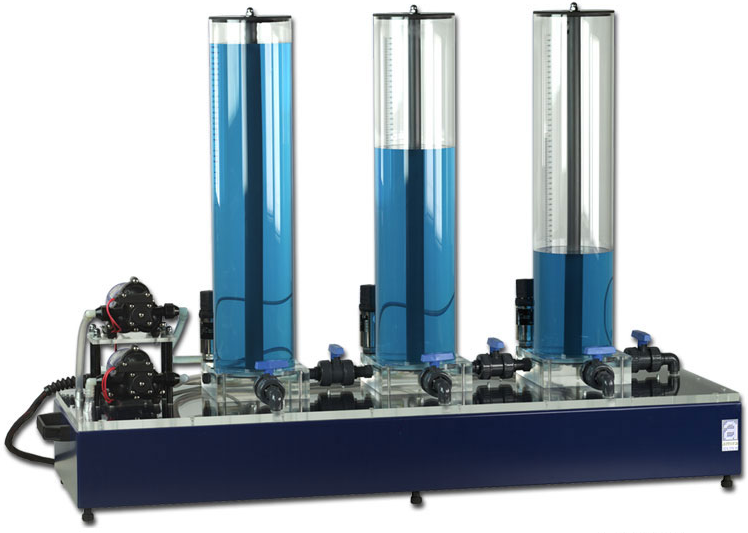

Fig. 1: The Three-Tank-System

These sensors are piezo-resistive pressure sensors, mounted beside the top of each of the three tanks

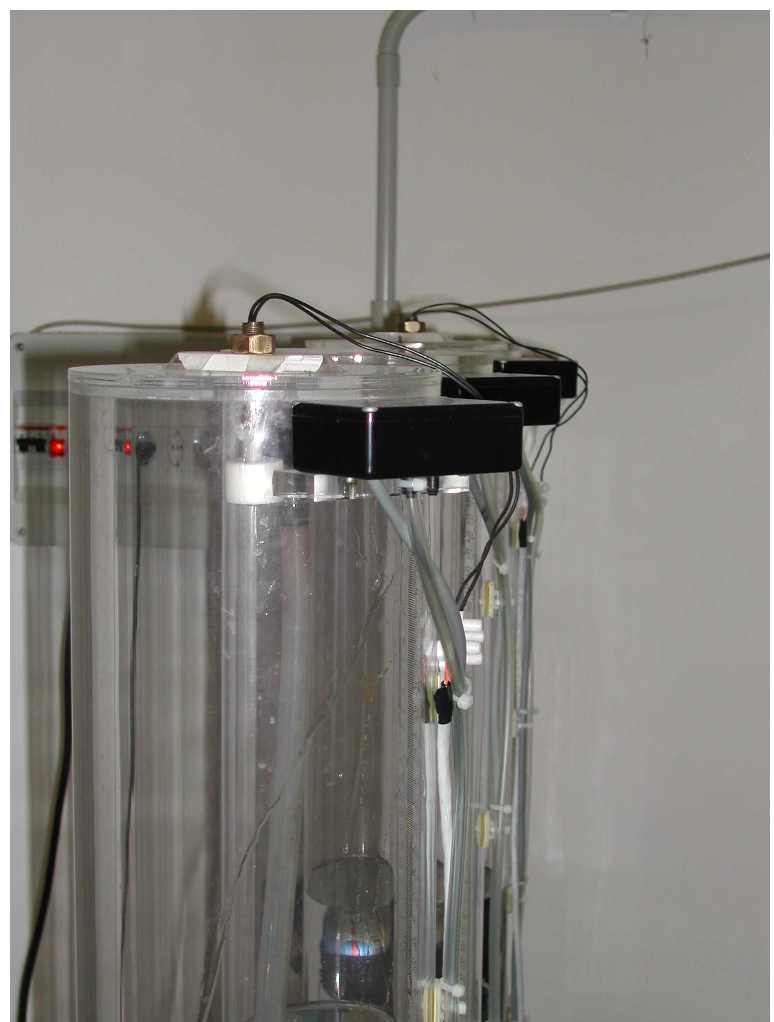 

Fig. 2: A piezoresistive sensor. Note the transparent tube that connects the sensor with the bottom of the cylinder and reports the pressure acting on the bottom of the tank to the sensor.  Note also the white nozzle, used to detect atmospheric pressure and subtract the contribution of air pressure, so that the device only detects the hydrostatic pressure due to the liquid in the tank.

During an experiment to calibrate the level sensors, we collected the following data from one of the level sensors: at predetermined liquid levels in the tank, the voltages provided by the sensor were acquired. The data are shown in the table:


$$\matrix{
\text{liquid level [mm]}    	& \text{voltage [V]} \cr
49 & 	9.74 \cr
98 & 	8.37 \cr
137 & 	7.27 \cr
203 & 	5.43 \cr
305 & 	2.54 \cr
397 & 	-0.05 \cr
504 & 	-2.98 \cr
576 & 	-5.02 \cr
499 & 	-2.91 \cr
402 & 	-0.23 \cr
305 & 	2.50 \cr
197 & 	5.50 \cr
98 & 	8.25 \cr
54 & 	9.51 \cr
}$$
  

Table (1): the preselected liquid levels and the corresponding voltage values, acquired using the sensor.

liquid_L = [49; 98; 137; 203; 305; 397; 504; ...
            576; 499; 402; 305; 197; 98; 54]; % levels [mm]
sensor_V = [9.74; 8.37; 7.27; 5.43; 2.54; -0.05;...
             -2.98; -5.02; -2.91; -0.23; 2.50; 5.50; 8.25; 9.51]; 
            % acquired voltage values [V]

Let's plot the raw data in a figure with the voltage on the x-axis and the level on the y-axis; we use a marker to identify each data value.

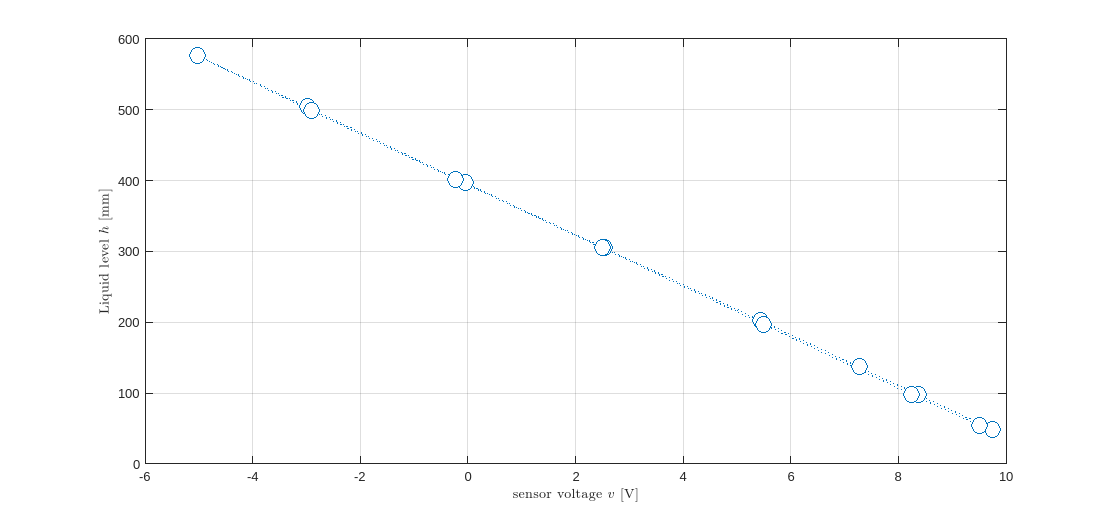

figure('Units','normalized', 'Position', [0.1, 0.1, .9, .75]);
plot(sensor_V, liquid_L,  "LineStyle", ":", "LineWidth", 1, ...
        "Marker","o","MarkerSize", 12, "MarkerEdgeColor","auto", "MarkerFaceColor","auto");
grid on;
ylabel('Liquid level $h$ [mm]','Interpreter','latex');
xlabel('sensor voltage $v$ [V]', 'Interpreter','latex')

The graph looks very similar to that of a linear (affine) function


$$h(t) = \vartheta_1 \, v(t) + \vartheta_2 = 
\left[ \begin{array}{cc} v(t) & 1 \end{array}\right]^{\top} \cdot \left[ 
\begin{array}{c}
\vartheta_1\\
\vartheta_2
\end{array} \right] = \varphi(t)^{\top} \cdot \vartheta$$


## How to Solve the Least-Squares Normal Equations Using MATLAB

Given $N$ observations, we build the following matrices and vectors


$$\Phi_N =
\left [
\begin{array}{c}
\varphi(1)^{\top} \\
\vdots \\
\varphi(N)^{\top}
\end{array}
\right ] 
\quad
\varphi (t)=
\left [
\begin{array}{c}
u_1(t) \\
\vdots \\
u_q(t)
\end{array}
\right ]
\qquad \vartheta =
\left [
\begin{array}{c}
\vartheta_1 \\
\vdots \\
\vartheta_q
\end{array}
\right ] 
\qquad Y_{N} =
\left [
\begin{array}{c}
y(1) \\
\vdots \\
y(N)
\end{array}
\right ]
$$


Now rewrite the regression problem in a compact form as


$$\Phi_{N}\cdot \vartheta = Y_{N}$$


To obtain the *LS normal equations* in compact form, simply multiply both terms of this expression to the left using the transposed matrix $\Phi_N^{\top}$:


$$\Phi_N^{\top} \, \Phi_N\,\vartheta = \Phi_N^{\top} \, Y_{N}$$


### Remark

Verify that


$$\Phi_N^{\top} \, \Phi_N = \left [ \,\sum_{t=1}^N \,\varphi(t)
\, \varphi(t)^{\top} \, \right ] \;,\qquad \Phi_N^{\top} \, Y_{N} = \left[ \sum_{t=1}^N \,
\varphi(t) \, y(t)  \right]$$


### The Moore-Penrose Pseudo Inverse Matrix

If the square matrix $\Phi_N^{\top}\,\Phi_N$ is invertible, then the solution of the LS normal equations becomes


$$\hat{\vartheta}_{N} = \left( \Phi_N^{\top}\,\Phi_N\right)^{-1}\,\Phi_N\,Y_N \qquad (\star)$$


The matrix $\left( \Phi_N^{\top}\,\Phi_N\right)^{-1}\,\Phi_N$ is called the [**Moore-Penrose pseudo inverse matrix**](https://en.wikipedia.org/wiki/Moore%E2%80%93Penrose_inverse) of $\Phi_N$.

### Solving an LS Problem using MATLAB

Two approaches are available: 

- use the command `pinv()` to find the solution exploiting the Moore-Penrose pseudo inverse matrix. Note that `pinv()` produces the pseudo inverse matrix only. In order to compute the solution of the LS normal equations we have to evaluate Eq. $(\star)$.

- apply the command `mldivide()`, given the matrix $\Phi_N$ and the vector $Y_N$, to compute directly the solution $\hat{\vartheta}_N$.

To have a look on the proposed commands syntax, in the MATLAB Command Window type the commands

Have also a look on the shorcutted command \

#### Important Remark

When the matrix $\Phi_N^{\top}\,\Phi_N$ is invertible both the proposed commands provide a similar answer.

## Exercise

Given the data described above, perform the following steps:

- solve a least squared regression problem to determine a linear static response curve for the sensor;

- plot the resulting curve on the same figure with the raw data.

% your code

% we have to define FI = [V ones] to be able to calculate the least squared
% regression

% FI * thetas = liquid_L
% => thetas = liquid_L \ sensor_V

FI = [sensor_V ones(length(liquid_L),1)];
thetas = FI \ liquid_L;

x = linspace(-6,10,20);
y = thetas(1) * x + thetas(2);

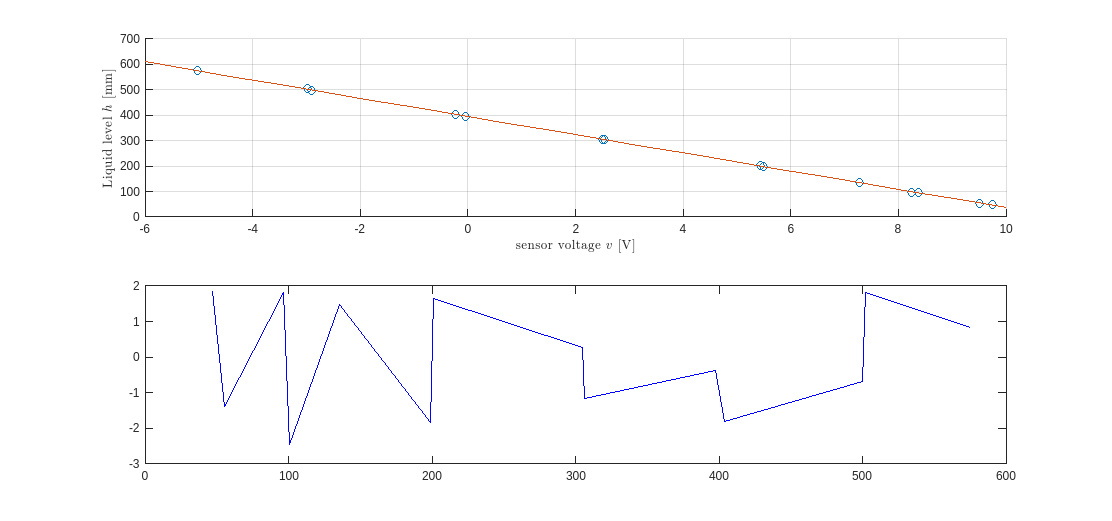

figure('Units','normalized', 'Position', [0.1, 0.1, .9, .75]);

subplot(2,1,1)

scatter(sensor_V, liquid_L);
grid on;
ylabel('Liquid level $h$ [mm]','Interpreter','latex');
xlabel('sensor voltage $v$ [V]', 'Interpreter','latex');
hold on;

plot(x, y)

hold off;
subplot(2,1,2)

grid on; 
y2 = thetas(1) * sensor_V + thetas(2);
errors = liquid_L - y2;

[ys, idx]= sort(y2);
plot(ys, errors(idx), '-b');

%plot(y2, errors, '-b');

mean(errors)

ans = 4.0602e-14

var(errors)

ans = 2.4869

## References

[1] D. S. Bernstein, "Sensor performance specifications," in *IEEE Control Systems Magazine*, vol. 21, no. 4, pp. 9-18, Aug. 2001, doi: 10.1109/37.939939.